# Detect Anomalies in Text Data Using Variational Autoencoder (VAE) in MATLAB® 

This example shows how to detect out-of-distribution text data using a variational autoencoder (VAE). 

VAEs are a neural network architecture composed of two parts:

- An encoder that encodes data in a lower-dimensional parameter space.

- A decoder that reconstructs the input data by mapping the lower-dimensional representation back into the original space.

You can use a VAE to detect anomalies in your dataset. To do this, train a VAE on your data. Then, encode and decode a test data point. Compare the output of the decoder with the input data. If the input and output are similar, then the data is in-distribution. If the input and output are dissimilar, then the data is out-of-distribution, or anomalous.

This example includes three steps.

1.	Load and preprocess the text data.

2.	Set up and train the encoder and decoder networks.

3.	Use the VAE to detect anomalies in test data

## Load and preprocess the text data

Load the example data. The file `factoryReports.csv` contains factory reports, including a text description and categorical labels for each report. 

To get the data, go to [https://www.mathworks.com/help/textanalytics/ug/create-simple-text-model-for-classification.html.](https://www.mathworks.com/help/textanalytics/ug/create-simple-text-model-for-classification.html.) Click on the button "Copy Command" on the top right of the page and paste it in MATLAB CLI. This will open the example in the directory where the .csv file is stored. Copy the .csv file from the example, and paste it in a local working directory of this example.

filename = "factoryReports.csv"; % point to the location where it is saved
data = readtable(filename,TextType="string");
textData = data.Description;

Partition the data into a training partition and a held-out test set. Specify the holdout percentage to be 10%.

cvp = cvpartition(numel(textData), 'Holdout', 0.1);
textDataTrain = textData(training(cvp),:);
textDataTest = textData(test(cvp),:);

Create a function which tokenizes and preprocesses the text data so it can be used for analysis. The function for preprocessing the text data, preprocessText, is shown at the end of the file.

documentsTrain = preprocessText(textDataTrain);

The next step is to convert the text into sequences of same length.

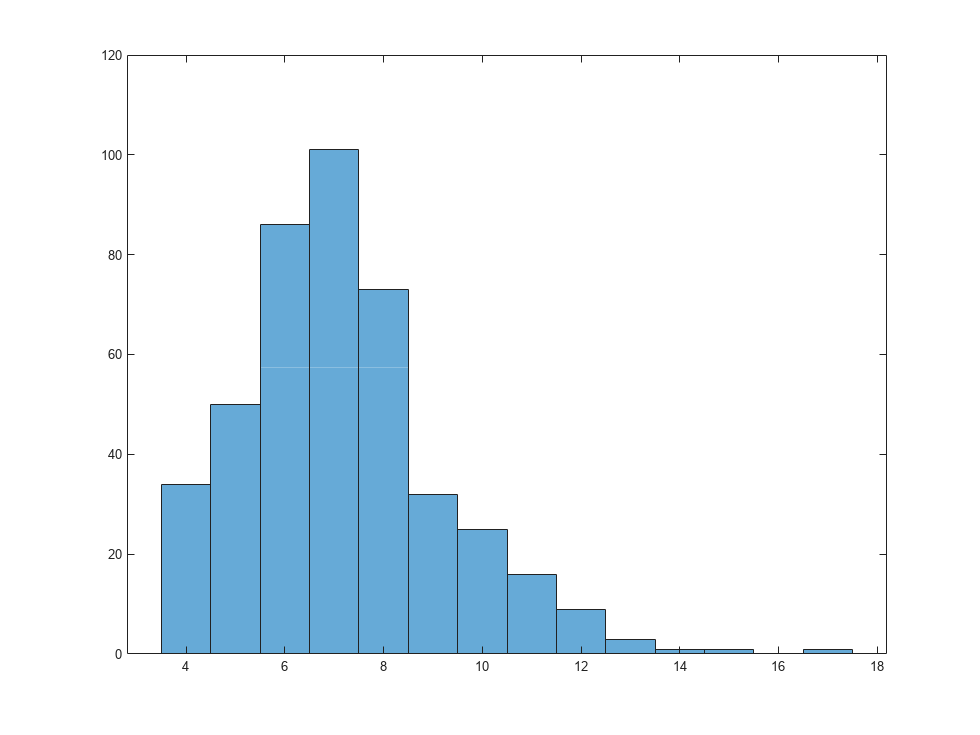

documentLengths = doclength(documentsTrain); % check for document length
histogram(documentLengths)

sequenceLength = 12; % max sequence length to be used for all training data

To create a word encoding, use the wordEncoding function:

enc = wordEncoding(documentsTrain); % create word encoding model from the training data
numWords = enc.NumWords; % total number of words to be used later in the model

ds = arrayDatastore(documentsTrain); % use arrayDatastore, if a large collection of data is used for training

Create a `minibatchqueue` object that processes and manages the mini-batches of data.

miniBatchSize = 64;

% creating mini-batches of data for training using custom training loops
mbq = minibatchqueue(ds,3, ...
    MiniBatchSize=miniBatchSize, ...
    MiniBatchFcn=@(X) preprocessMiniBatch(X, enc, sequenceLength), ...
    MiniBatchFormat=["CTB" "CTB" "CTB"], ...
    PartialMiniBatch="discard");

## Set up and train the encoder and decoder networks

Autoencoders have two parts: the encoder and the decoder. 

- The encoder takes a sequence of text data and outputs a latent vector representation (the encoding) using a series of layers such as LSTMs. Similarly, the decoder takes as input the latent vector representation, and reconstructs the input using another series of layers such as LSTMs.To sample the input, the example uses the custom layer `samplingLayer (samplingLayer.m). `The layer takes as input the mean vector *μ* concatenated with the log-variance vector log(*σ*2) and samples elements from *N*(*μ**i*,*σ*2*i*). The layer uses the log-variance to make the training process more numerically stable.

- The decoder reconstructs the sequence from the latent feature vector. For feature vector input, specify a feature input layer with input size matching the number of latent channels. Project and reshape the latent input to bring back the sequence dimension (T) using the custom layer `projectAndReshapeLayer`, attached to this example as a supporting file. To upsample the input, pass the sequence through a series of layers to bring it back to the length of number of words in the dictionary. 

inputSize = 1;

hiddenUnits = 64;
numLatentChannels = 32;
embeddingDimension = 50;

projectionSize = [1 sequenceLength];

% Encoder layers

layersE = [
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension, numWords)

    lstmLayer(2*hiddenUnits)
    eluLayer
    lstmLayer(hiddenUnits, "OutputMode","last")
    eluLayer


    fullyConnectedLayer(2*numLatentChannels)

    samplingLayer
    ];

% Decoder layers

layersD = [
    featureInputLayer(numLatentChannels)
    projectAndReshapeLayer(projectionSize)

    lstmLayer(hiddenUnits)
    eluLayer
    lstmLayer(2*hiddenUnits)
    eluLayer
    lstmLayer(4*hiddenUnits)
    eluLayer

    fullyConnectedLayer(numWords)

    softmaxLayer
    ];


To train both networks with a custom training loop and enable automatic differentiation, convert the layer arrays to `dlnetwork` objects.

netE = dlnetwork(layersE);
netD = dlnetwork(layersD);

Train for 1000 epochs and initialize the parameters for the Adam solver.

numEpochs = 1000;

learnRate = 0.001;
trailingAvgE = [];
trailingAvgSqE = [];
trailingAvgD = [];
trailingAvgSqD = [];

Initialize the training progress monitor.

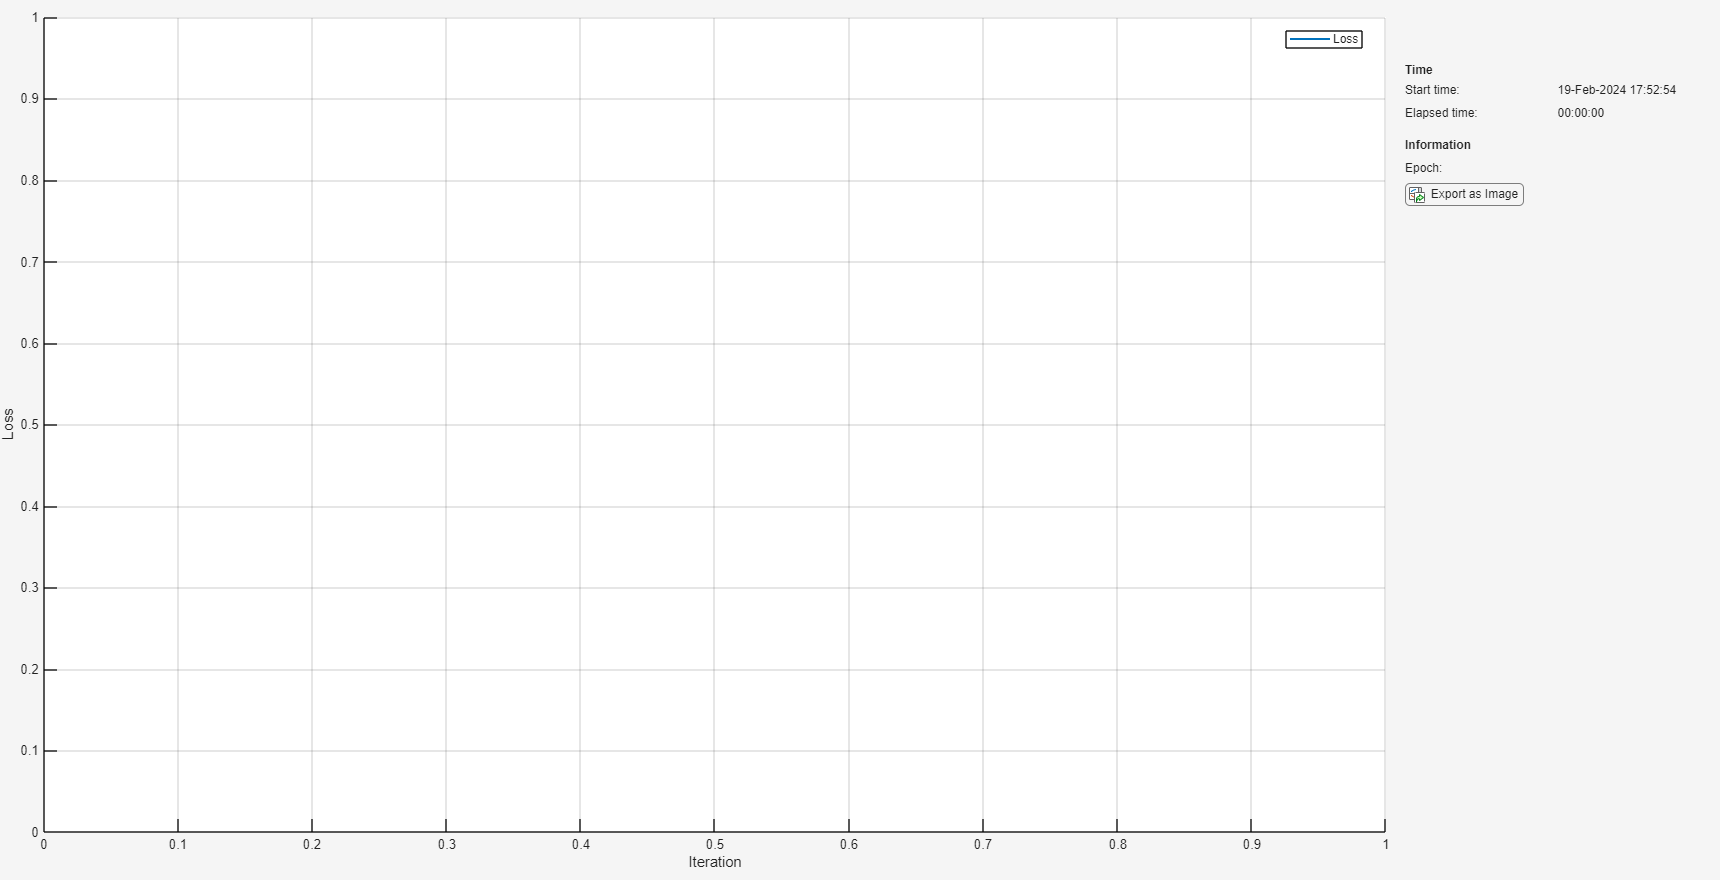

monitor = trainingProgressMonitor( ...
    Metrics="Loss", ...
    Info="Epoch", ...
    XLabel="Iteration");

Train the network using a custom training loop. For each epoch, shuffle the data and loop over mini-batches of data. For each mini-batch:

- Evaluate the model loss and gradients using the `dlfeval` and `modelLoss` functions.

- Update the encoder and decoder network parameters using the `adamupdate` function.

- Display the training progress.

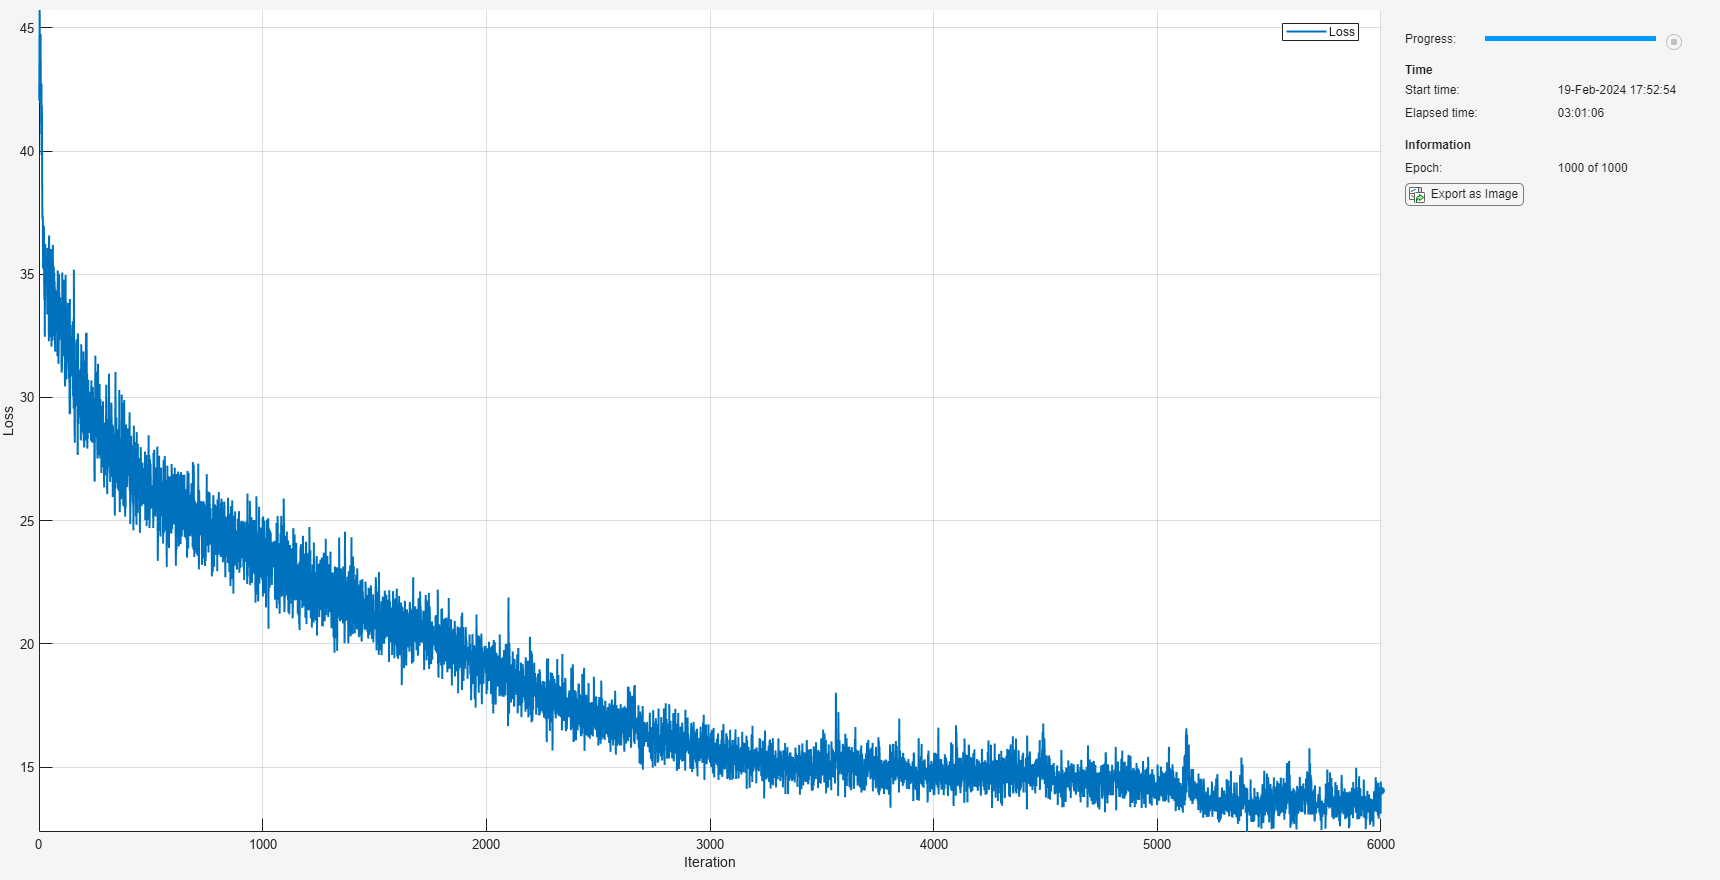

numObservationsTrain = size(documentsTrain,1);
numIterationsPerEpoch = floor(numObservationsTrain / miniBatchSize);
numIterations = numEpochs * numIterationsPerEpoch;

epoch = 0;
iteration = 0;

% Loop over epochs.
while epoch < numEpochs && ~monitor.Stop
    epoch = epoch + 1;

     % Shuffle data.
    shuffle(mbq);

    % Loop over mini-batches.
    for i = 1:numIterationsPerEpoch
        iteration = iteration + 1;
       
        % Read mini-batch of data.
        [X, T, maskT] = next(mbq);


        beta = epoch/numEpochs;
        % Evaluate loss and gradients.
        [loss,gradientsE,gradientsD] = dlfeval(@modelLoss,netE,netD,X,T,maskT,beta);
        
        % Update learnable parameters.
        [netE,trailingAvgE,trailingAvgSqE] = adamupdate(netE, ...
            gradientsE,trailingAvgE,trailingAvgSqE,iteration,learnRate);

        [netD, trailingAvgD, trailingAvgSqD] = adamupdate(netD, ...
            gradientsD,trailingAvgD,trailingAvgSqD,iteration,learnRate);

        % Update the training progress monitor. 
        recordMetrics(monitor,iteration,Loss=loss);
        updateInfo(monitor,Epoch=epoch + " of " + numEpochs);
        monitor.Progress = 100*iteration/numIterations;

    end
end

## Use the VAE to detect anomalies in test data

Test to check if the model recognizes the data it is trained with and the data it has not seen before. Since VAEs use probabilistic distributions to reconstruct the original input, you can generate multiple outputs from the same input. Here we are reconstructing an input 5 times and estimating similarities with the original text. The heatmap of similarities shows which data the model has seen before and which one it has not. 

str = [
    textDataTrain(51) % data from training set
    "there is nothing I can do for you" % never-seen before data
    ];

inpStr = preprocessText(str);
processedStr = preprocessPredictors(inpStr, enc, sequenceLength);
processedStr = dlarray(processedStr, "CTB");

numGenSentences = 5;
genSentences = strings(size(str,1), numGenSentences);
similarities = zeros(size(str,1), numGenSentences);

for jj = 1:size(str, 1)
    for ii = 1:numGenSentences
        [Z,mu,logSigmaSq] = predict(netE,processedStr);
        Y = predict(netD,Z);
        [a,b] = max(Y);
        b = squeeze(extractdata(b));
        genSentences(jj,ii) = strjoin(ind2word(enc, b));
    end
    tokGenSentences = tokenizedDocument(genSentences);
    similarities(jj, :) = bm25Similarity(tokGenSentences(jj, :),inpStr(jj))
end

similarities =     0.0994    0.0403    1.1390    0.1363    0.8402
         0         0         0         0         0


similarities =     0.0994    0.0403    1.1390    0.1363    0.8402
         0         0         0         0         0


genSentences

genSentences = 2×5 string array
    "things strange keep rattling falling sounds off in the mixer belt . . . . . . . . . . . . ."    "fuse strange are rattling falling sounds off in the mixer conveyor . . . . . . . . . . . . ."      "fuse strange are rattling falling sounds in from the mixer conveyor . . . . . . . . . . . . ."    "things smoke keep rattling fall inside off the the mixer belt . . . . . . . . . . . . ."         "fuse smoke are rattling fall inside into the the mixer spool . line . . . . . . . . . . ."   
    "fuse loud are rattling falling sounds off in the mixer item . . . . . . . . . . . . ."          "fuse smoke are rattling falling inside off the the mixer conveyor . line . . . . . . . . . . ."    "fuse loud are rattling falling sounds off from the mixer conveyor . . . . . . . . . . . . ."      "fuse loud are rattling falling emerging in from the mixer conveyor . . . . . . . . . . . . ."    "fuse loud are rattling falling emerging in from the mixer conveyor . . . . .

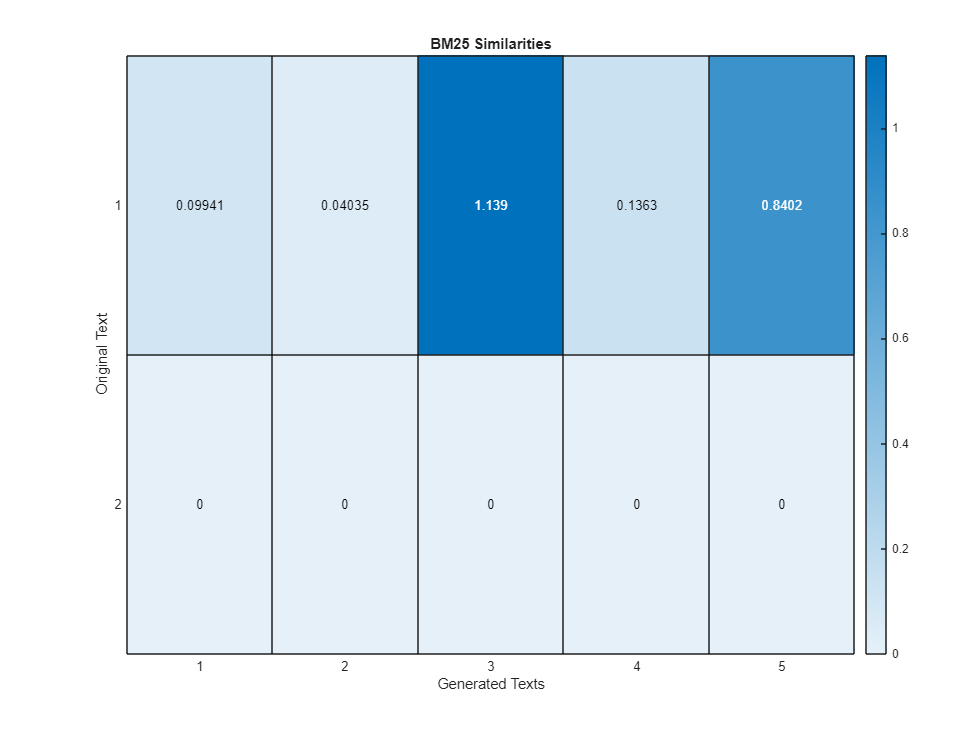

figure
heatmap(similarities);
xlabel("Generated Texts")
ylabel("Original Text")
title("BM25 Similarities")

### Preprocess text data

function documents = preprocessText(str)

str = lower(str);
documents = tokenizedDocument(str);

end


#### Preprocess minibatches of data

function [X, T, mask] = preprocessMiniBatch(data,enc,sequenceLength)

documents = cat(1,data{:});
X = preprocessPredictors(documents,enc,sequenceLength);

sequencesTarget = doc2sequence(enc,documents,PaddingDirection="none");

[T,mask] = padsequences(sequencesTarget,2,"PaddingValue",1,"Length",sequenceLength);

end

function X = preprocessPredictors(X,enc,sequenceLength)

sequencesSource = doc2sequence(enc,X,PaddingDirection="none");
X = padsequences(sequencesSource,2,"Length",sequenceLength);

end


### Loss functions

function [loss,gradientsE,gradientsD] = modelLoss(netE,netD,X,T,maskT,beta)

% Forward through encoder.
[Z,mu,logSigmaSq] = forward(netE,X);


% Forward through decoder.
Y = forward(netD,Z);

% Calculate loss and gradients.
loss = elboLoss(Y,T,mu,logSigmaSq,maskT,beta);
[gradientsE,gradientsD] = dlgradient(loss,netE.Learnables,netD.Learnables);

end

function loss = elboLoss(Y,T,mu,logSigmaSq,maskT,beta)

% Reconstruction loss.
reconstructionLoss = sparseCrossEntropy(Y,T,maskT);

% KL divergence.
KL = -0.5 * sum(1 + logSigmaSq - mu.^2 - exp(logSigmaSq),1);
KL = mean(KL);

% Combine loss using weight, beta (inspired by the concept of KL annealing
% from https://arxiv.org/pdf/1511.06349.pdf) 
loss = reconstructionLoss + beta*KL;

end

function loss = sparseCrossEntropy(Y,T,maskT)

% Initialize loss.
[~,miniBatchSize,sequenceLength] = size(Y);
loss = zeros([miniBatchSize sequenceLength],"like",Y);

% To prevent calculating log of 0, bound away from zero.
precision = underlyingType(Y);
Y(Y < eps(precision)) = eps(precision);

% Loop over time steps.
for n = 1:miniBatchSize
    for t = 1:sequenceLength
        idx = T(1,n,t);
        loss(n,t) = -log(Y(idx,n,t));
    end
end

% Apply masking.
maskT = squeeze(maskT);
loss = loss .* maskT;

% Calculate sum and normalize.
loss = sum(loss,"all");
loss = loss / miniBatchSize;

end


## Reference

- Generating Sentences from a Continuous Space, Samuel R. Bowman, Luke Vilnis, Oriol Vinyals, Andrew M. Dai, Rafal Jozefowicz & Samy Bengio, [https://arxiv.org/pdf/1511.06349.pdf](https://arxiv.org/pdf/1511.06349.pdf) 

*Copyright 2024 The MathWorks, Inc.*